# Time domain analysis

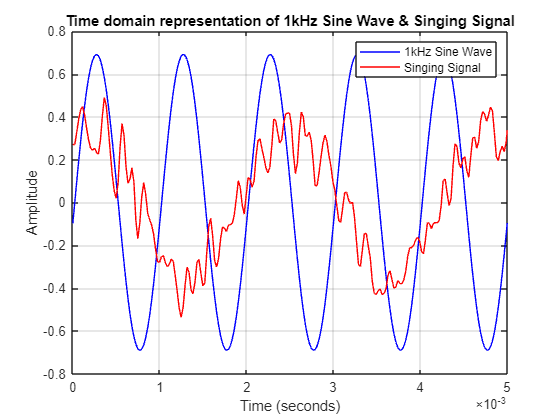




% Load proper 1kHz sine sound file
[sine1k_clean, fs_sine1k_clean] = audioread(['..', filesep, 'Aflevering 1', filesep, ...
                '1kHz_44100Hz_16bit_05sec.wav']); 

% Load the recording of the singing
[singing, fs_singing] = audioread(['..', filesep, 'Aflevering 1', filesep, ...
                'record_out.wav']); 

% Resample singing signal to match the sine wave sampling rate
singing_resample = resample(singing, fs_sine1k_clean, fs_singing);

% Duration of signals
T = 0.5;


n_samples = fs_sine1k_clean * T;  % Number of samples for 0.5 seconds

n_2s = fs_sine1k_clean * 2;  % Number of samples for 2 seconds

% Extract the 0.5 second segment from the sine wave
sine_half_second = sine1k_clean(n_2s:n_2s + n_samples - 1);

% Extract the 0.5 second segment from the resampled singing signal
singing_half_second = singing_resample(n_2s:n_2s + n_samples - 1);

% Create time vector for the new 0.5 second signals
t_half_second = (0:n_samples-1) / fs_sine1k_clean;

% Plot both signals on the same plot
figure1 = figure;
plot(t_half_second, sine_half_second, '-b');  % Plot sine wave in blue
hold on;
plot(t_half_second, singing_half_second, '-r');  % Plot singing signal in red
hold off;

% Add labels, title, and legend
xlim([0 0.005])
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Time domain representation of 1kHz Sine Wave & Singing Signal');
legend('1kHz Sine Wave', 'Singing Signal');
grid on
hold off

## Frequency analysis

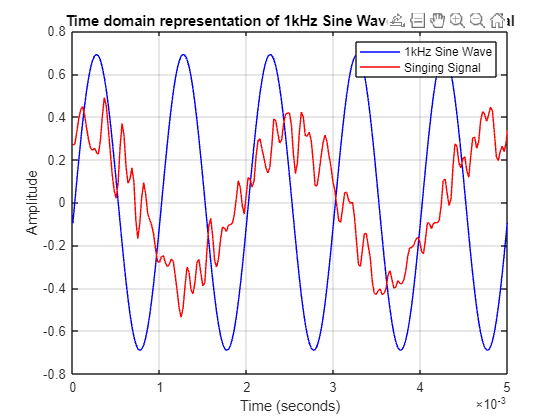




fft_sine = fftshift(fft(sine_half_second));
fft_singing = fftshift(fft(singing_half_second));

abs_singing = abs(fft_singing);
abs_sine = abs(fft_sine);

abs_singing_dB = 20*log10(abs_singing/max(abs_singing));
abs_sine_dB = 20*log10(abs_sine/max(abs_singing));

length(fft_singing); %Check whether it's odd or not, in order to make frequency vector

Delta_f = (-fs_sine1k_clean/2+1/T:1/T:fs_sine1k_clean/2);

figure2 = figure;
plot(Delta_f, abs_singing_dB, '-r');  % Plot singing signal in red
hold on;
plot(Delta_f, abs_sine_dB, '-b');     % Plot sine signal in blue
xlim([-3000 3000]);                   % Set x-axis limits

title('Frequency Domain Representation of Singing and Sine Signals');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB), referenced using max of singing signal');
legend('Singing Signal', '1kHz Sine Wave', 'Location','southeast');
grid on;
hold off

saveas(figure1,'Assignment1_TD','png')

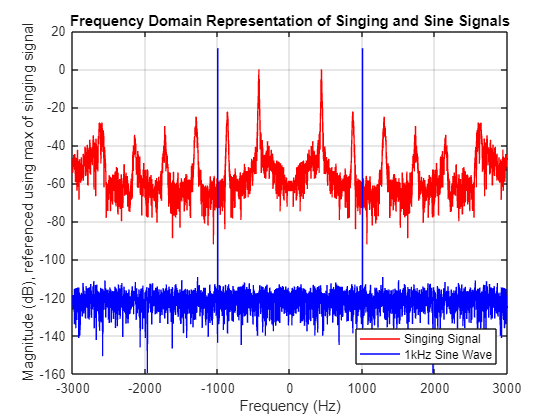

saveas(figure2,'Assignment1_FD', 'png')